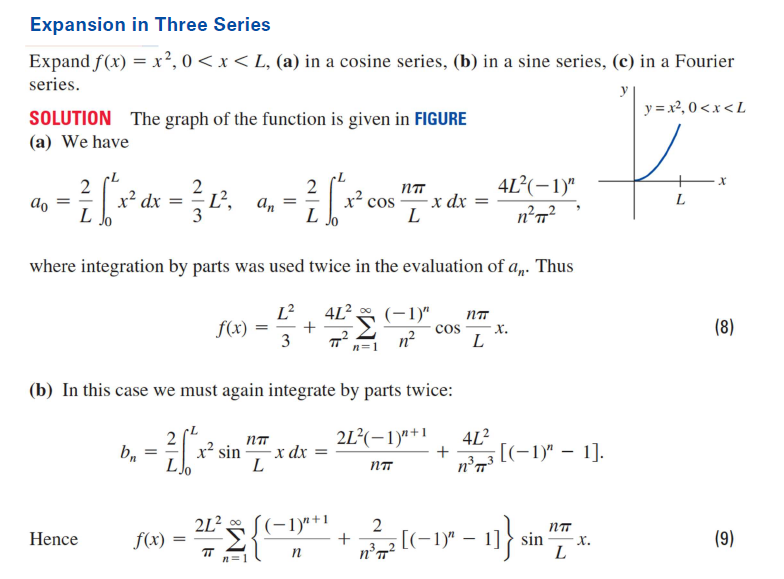

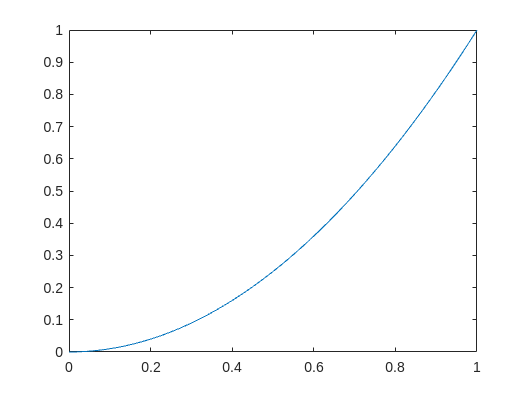

clear
clf
clc

syms x 
L = 1;

ft = x^2;
fplot(ft, [0, L])


N = 50; % number of harmonics 
n = 1:N;

a0 = (2/L) * int(ft, x, 0, L);
a_n = (2/L) * int(ft * cos(pi*n/L*x), x, 0, L);
b_n = (2/L) * int(ft * sin(pi*n/L*x), x, 0, L);

A_n = a0/2;
for i = 1:N
    A_n = A_n + a_n(i) * cos(pi*i/L*x);
end

fprintf("f(x) in a cosine series\n");

f(x) in a cosine series


disp(A_n);

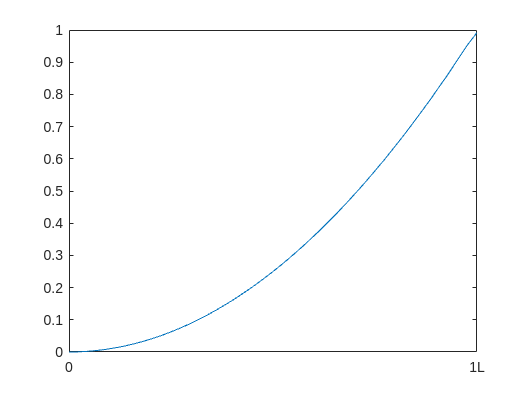


fplot(A_n, [0, L]);
xticks([-5 -4 -3 -2 -1 0 1 2 3 4 5] * L);
xticklabels({'-5L','-4L','-3L','-2L','-1L','0','1L','2L','3L','4L','5L'});


%-----------------------------------------

B_n = 0;
for i = 1:N
    B_n = B_n + b_n(i) * sin(pi*i/L*x);
end

fprintf("f(x) in a sine series\n");

f(x) in a sine series


disp(B_n);

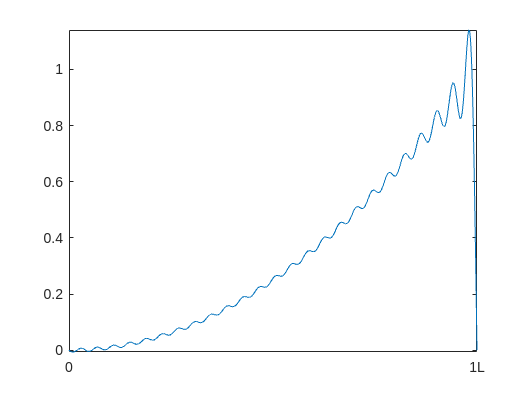


figure;
fplot(B_n, [0, L]);
xticks([-5 -4 -3 -2 -1 0 1 2 3 4 5]);
xticklabels({'-5L','-4L','-3L','-2L','-1L','0','1L','2L','3L','4L','5L'});


%-----------------------------------------

F_n = a0/2;
for i = 1:N
    F_n = F_n + a_n(i) * cos(pi*i/L*x) + b_n(i) * sin(pi*i/L*x);
end

fprintf("f(x) in a Fourier series\n");

f(x) in a Fourier series


disp(F_n);

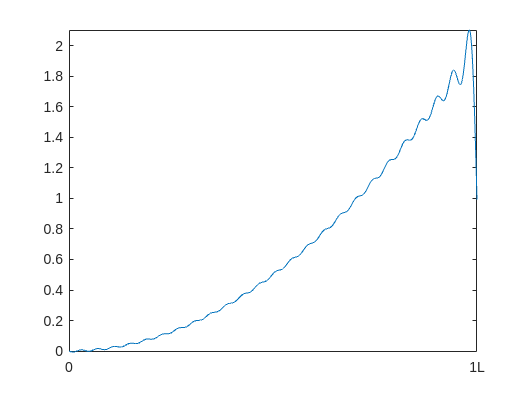


figure;
fplot(F_n, [0, L]);
xticks([-5 -4 -3 -2 -1 0 1 2 3 4 5] );
xticklabels({'-5L','-4L','-3L','-2L','-1L','0','1L','2L','3L','4L','5L'});